clc;
clear all;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=100;
t = 0:T_s:tfinal;
Priemss=primes(100);
u=zeros(numel(t),1);
% for i=15:numel(Priemss)
%     input_dummy=gensig('sine' , tfinal/Priemss(1,i) , tfinal ,T_s);
%     u=u+input_dummy;
% end
u = gensig('pulse' , tfinal/10 , tfinal ,T_s);
% Noise=0.01*rand(numel(t),1)
% u=u+Noise
y = lsim(sysd  ,u ,t);
% plot(t,u ,t , y ,'LineWidth',2) ;
% xlabel('Time (sec)') ;
% ylabel('V - position') ;
% title('square ressponse of Question 2') ;
% grid on
% legend(['U' , 'position']) ;

## PA estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

theta(:,1:30) = 30*ones(Nv,30);
phi=[];

alfa=0.005

alfa = 0.0050

gama=1

gama = 1


for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))',(u(i-1:-1:i-Parameters_in_num))']';
    error=gama*phi(:,i)*(y(i) - phi(:,i)'*theta(:,i-1))/(alfa+phi(:,i)'*phi(:,i));
    theta(:,i) = theta(:,i-1) +error; 
    norm(error);
end
theta(:,i)

ans =     0.2814
   -0.3051
   -0.0801
    0.8283
    0.0002
    0.0022
    0.0058
    0.0106


ident_dis = tf(theta(Parameters_in_num+1:end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
  0.0001931 z^3 + 0.002225 z^2 + 0.005756 z + 0.0106
  --------------------------------------------------
  z^4 - 0.2814 z^3 + 0.3051 z^2 + 0.0801 z - 0.8283
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
       0.04869 s^4 - 1.107 s^3 + 33.83 s^2 - 407.2 s + 3402
  ---------------------------------------------------------------
  s^5 + 2.767 s^4 + 723.4 s^3 + 512.1 s^2 + 7.705e04 s + 4.992e04
 
Continuous-time transfer function.



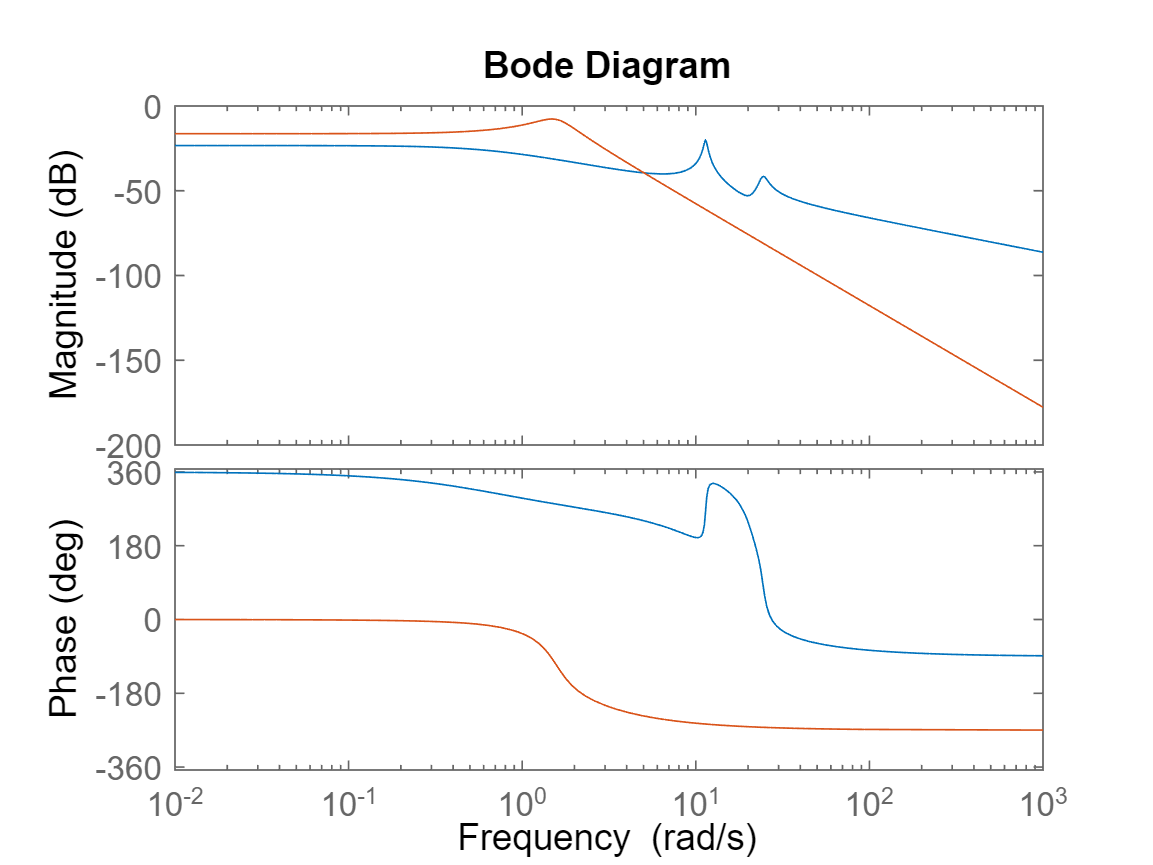

bode(ident_analog ,sys )

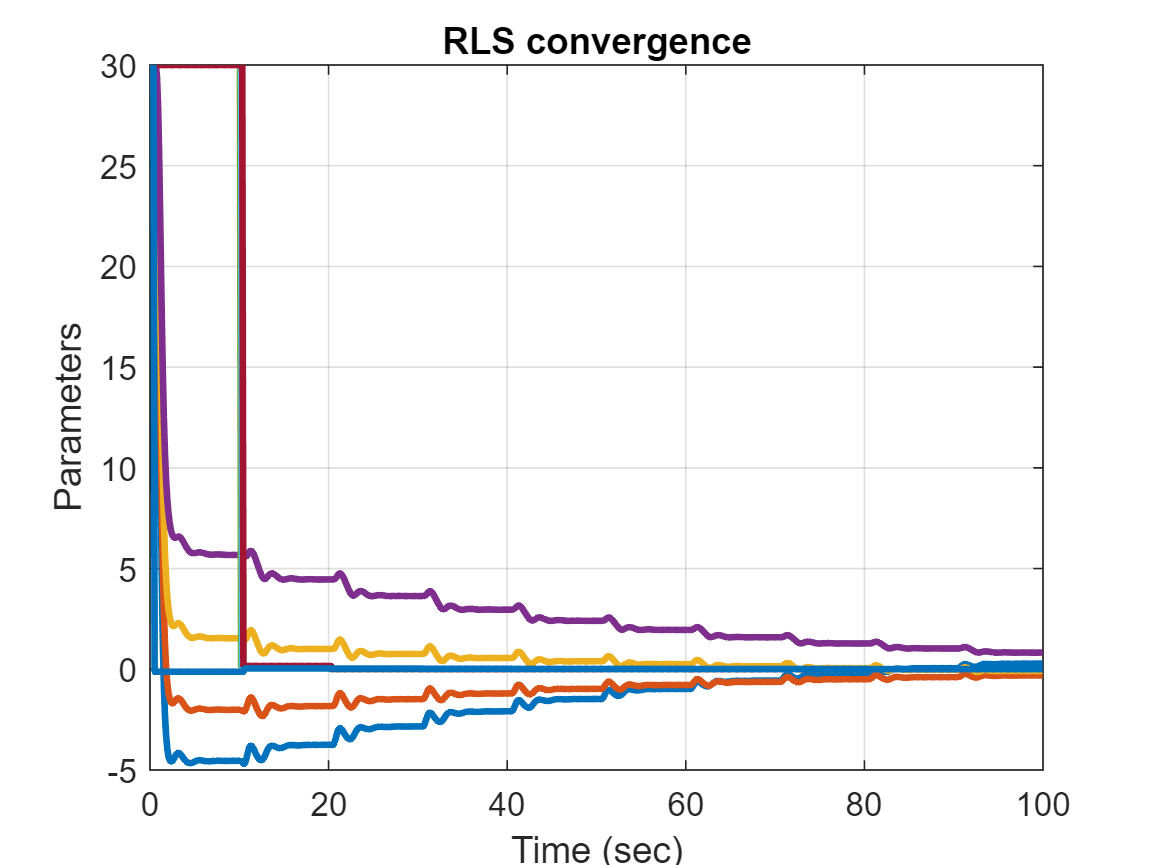


plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence') ;
grid on